clc
clear all;

# LOAD DATA & STEPS CALCULATION

[lat_sit, lon_sit, positionTime_sit, Xacc_sit, Yacc_sit, Zacc_sit, accelTime_sit, steps_sitting] = loadActivityData("new_sitting");

The total distance traveled is: 0.0085944 miles
You took 18.1513 steps


[lat_walk, lon_walk, positionTime_walk, Xacc_walk, Yacc_walk, Zacc_walk, accelTime_walk, steps_walking] = loadActivityData("new_walking");

The total distance traveled is: 0.26691 miles
You took 563.7119 steps


[lat_run, lon_run, positionTime_run, Xacc_run, Yacc_run, Zacc_run, accelTime_run, steps_running] = loadActivityData("new_running");

The total distance traveled is: 0.69359 miles
You took 1464.8572 steps


# CALORIES CALCULATION


calories_running = calculateCalories("running", positionTime_run);
calories_walking = calculateCalories("walking", positionTime_walk);
calories_sitting = calculateCalories("sitting", positionTime_sit);


# VISUALIZING

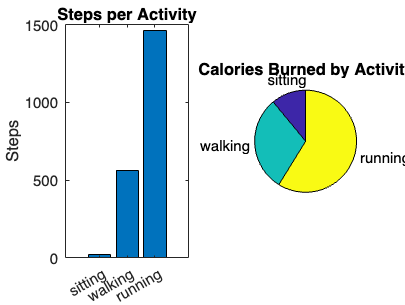

% Suppose you already processed:
activities = {'sitting', 'walking', 'running'};
steps = [steps_sitting, steps_walking, steps_running];
calories = [calories_sitting, calories_walking, calories_running];

visualizeResults(activities, steps, calories);

# ML SECTION

## SPLIT DATA

% Create activity label
Label_sit = repmat("new_sitting", length(Xacc_sit), 1);
Label_walk = repmat("new_walking", length(Xacc_walk), 1);
Label_run = repmat("new_running", length(Xacc_run), 1);

% Combine into one table
sitData = table(Xacc_sit, Yacc_sit, Zacc_sit, Label_sit, ...
    'VariableNames', {'X','Y','Z','Activity'});
walkData = table(Xacc_walk, Yacc_walk, Zacc_walk, Label_walk, ...
    'VariableNames', {'X','Y','Z','Activity'});
runData = table(Xacc_run, Yacc_run, Zacc_run, Label_run, ...
    'VariableNames', {'X','Y','Z','Activity'});

allData = [sitData; walkData; runData];

# EVALUATION MODEL

[~, ~, ~, Xacc_test, Yacc_test, Zacc_test, time, ~] = loadActivityData("test");

The total distance traveled is: 0.26422 miles
You took 558.0308 steps



% Build feature table
testData = table(Xacc_test, Yacc_test, Zacc_test, 'VariableNames', {'X','Y','Z'});

predictedLabels = trainedModel.predictFcn(testData);
pie(categorical(predictedLabels))
title("Predicted Activity Breakdown");


Error using categorical
Could not find unique values in DATA using the UNIQUE function.

Caused by:
    Error using matlab.internal.math.uniqueCellstrHelper
    Cell array input must be a cell array of character vectors.